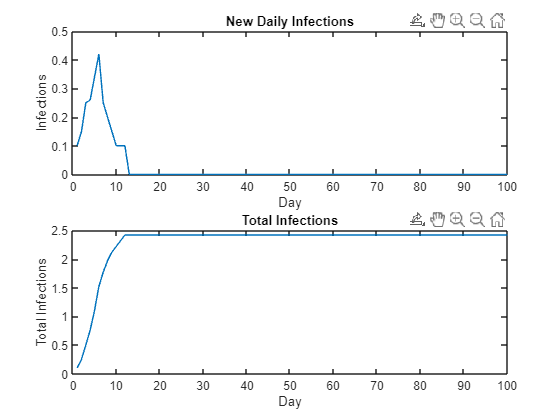

% Coefficients for the filter
a = [0.1, 0.15, 0.25, 0.26, 0.34, 0.42, 0.25, 0.2, 0.15, 0.1, 0.1, 0.1];

% Number of days to simulate
n = 100;

% Plot infections
plotInfections(a, n);

function plotInfections(a, n)
    % a: Coefficients for the filter
    % n: Number of days to simulate
    
    % Initialize the filter
    b = 1;  % Numerator coefficients (1 for integrator)
    filterOrder = length(a);
    
    % Generate Kronecker delta input
    delta = zeros(1, n);
    delta(1) = 1;
    
    % Initialize output signals
    newDailyInfections = zeros(1, n);
    totalInfections = zeros(1, n);
    
    % Simulate the response without lsim
    for t = 1:n
        % Update new daily infections
        for k = 1:min(t, filterOrder)
            newDailyInfections(t) = newDailyInfections(t) + a(k) * delta(t - k + 1);
        end
        
        % Update total infections
        if t > 1
            totalInfections(t) = totalInfections(t - 1) + newDailyInfections(t);
        else
            totalInfections(t) = newDailyInfections(t);
        end
    end
    
    % Plot new daily infections
    figure;
    subplot(2,1,1);
    plot(newDailyInfections);
    title('New Daily Infections');
    xlabel('Day');
    ylabel('Infections');
    
    % Plot total infections
    subplot(2,1,2);
    plot(totalInfections);
    title('Total Infections');
    xlabel('Day');
    ylabel('Total Infections');
end